clf
clear all

n = 2581;
m = 216;
MC = readtable('monthly reconsMC.xlsx','Sheet','84slope','VariableNamingRule','preserve');
TSST = readtable('SST.xlsx');

TSSS = readtable('SSS.xlsx','Sheet','SSS 5m');

SODA_centred = TSSS.SODA-mean(TSSS.SODA,'omitnan');
IAP_centred = TSSS.IAP - mean(TSSS.IAP,'omitnan');
EN4_centred = TSSS.EN4 - mean(TSSS.EN4,'omitnan');
TSrCa = readtable('monthly raw data.xlsx','Sheet','SrCa');

Td18O = readtable('monthly raw data.xlsx','Sheet','d18O');


SrCa_centred = TSrCa.SrCa - mean(TSrCa.SrCa,'omitnan');
d18O_centred = Td18O.d18O - mean(Td18O.d18O,'omitnan');
ERSSTv5_centred = TSST.ERSSTv5 - mean(TSST.ERSSTv5(n:end),'omitnan');
HadISST1_centred =TSST.HadISST - mean(TSST.HadISST(n:end),'omitnan');
gamma1 = -0.22; %average slope of d18O - SST
d18Osw_c_HadISST1 = d18O_centred - gamma1*HadISST1_centred;
d18Osw_c_ERSSTv5 = d18O_centred - gamma1*ERSSTv5_centred;

d18Osw_centred = MC.d18Osw;
d18Osw_centred_l =MC.("2.5cl_1");
d18Osw_centred_u =MC.("97.5cl_1");
d18Osw_centred_l2 =MC.("16cl_1");
d18Osw_centred_u2 =MC.("84cl_1");
errordate = vertcat(MC.Date,flipud(MC.Date));
errd18Osw_MC95 = vertcat(d18Osw_centred_u,flipud(d18Osw_centred_l));
errd18Osw_MC68 = vertcat(d18Osw_centred_u2,flipud(d18Osw_centred_l2));


SeasonSSS= readtable("Seasonality.xlsx",'Sheet','SSS_61_90');
sBM_SSS = vertcat(SeasonSSS.BMl,flipud(SeasonSSS.BMu));
sEN4 = vertcat(SeasonSSS.EN4l,flipud(SeasonSSS.EN4u));
sSODA = vertcat(SeasonSSS.SODAl,flipud(SeasonSSS.SODAu));
sBMERSSTv5_SSS = vertcat(SeasonSSS.BMERSSTv5l,flipud(SeasonSSS.BMERSSTv5u));
sBMHadISST1_SSS = vertcat(SeasonSSS.BMHadISST1l,flipud(SeasonSSS.BMHadISST1u));
seasonSSSMon = vertcat(SeasonSSS.Mon,flipud(SeasonSSS.Mon));
mean((d18Osw_centred_u(n:end)-d18Osw_centred_l(n:end))/2)

ans = 0.2192

wind = readtable('Winds.xlsx','Sheet','SSS');
wind2 = readtable('Winds.xlsx','Sheet','Sheet2');

rainfall = readtable('BMrainfall.xlsx');
PE = readtable('PE.xlsx');

# Figure 5.6a

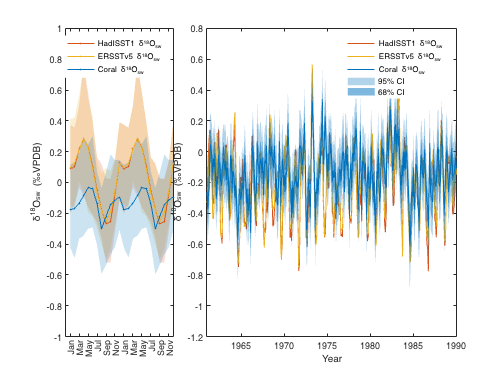

close
clf

subplot(1,3,1)
hold on 
patch(seasonSSSMon,sBMHadISST1_SSS,[0.8500 0.3250 0.0980],'Edgecolor','none','Facealpha',0.2)
patch(seasonSSSMon,sBMERSSTv5_SSS,[0.9290 0.6940 0.1250],'Edgecolor','none','Facealpha',0.2)
patch(seasonSSSMon,sBM_SSS,[0 0.4470 0.7410],'Edgecolor','none','Facealpha',0.2)
plot(SeasonSSS.Mon,SeasonSSS.BMHadISST1,'color',[0.8500 0.3250 0.0980],'LineWidth',1,'Marker','.','linestyle','-');
plot(SeasonSSS.Mon,SeasonSSS.BMERSSTv5,'color',[0.9290 0.6940 0.1250],'LineWidth',1,'Marker','.','linestyle','-');
plot(SeasonSSS.Mon,SeasonSSS.BM,'color',[0 0.4470 0.7410],'LineWidth',1,'Marker','.','linestyle','-');
set(gca,'ylim',[-1 1])
legend('','','','HadISST1 \delta^{18}O_{sw}','ERSSTv5 \delta^{18}O_{sw}','Coral \delta^{18}O_{sw}');
xticks(1:2:24)
xticklabels({'Jan','Mar','May','Jul','Sep','Nov','Jan','Mar','May','Jul','Sep','Nov'})
ylabel('\delta^{18}O_{sw} (‰VPDB)')
box on
set(legend,'box','off')

subplot(1,3,[2,3])
hold on
plot(MC.Date,d18Osw_c_HadISST1,'color',[0.8500 0.3250 0.0980],'linestyle','-','linewidth',1)
plot(MC.Date,d18Osw_c_ERSSTv5,'color',[0.9290 0.6940 0.1250],'linestyle','-','linewidth',1)
plot(MC.Date,d18Osw_centred,'color',[0 0.4470 0.7410],'linestyle','-','linewidth',1)
patch(errordate,errd18Osw_MC95,[0 0.4470 0.7410],'Edgecolor','none','Facealpha',0.3)
patch(errordate,errd18Osw_MC68,[0 0.4470 0.7410],'Edgecolor','none','Facealpha',0.5)
ylabel('\delta^{18}O_{sw} (‰VPDB)')
set(gca,'xlim',[1961 1990])
box on 
lg =legend('HadISST1 \delta^{18}O_{sw}', 'ERSSTv5 \delta^{18}O_{sw}','Coral \delta^{18}O_{sw}','95% CI','68% CI','location','northeast');
set(lg,'box','off')
set(gca,'ylim',[-1.2 0.8])
xlabel('Year')
ylabel('\delta^{18}O_{sw} (‰VPDB)')

# Figure 5.6b

close
clf
SeasonSSS= readtable("Seasonality.xlsx",'Sheet','SSS_LIA');
sBM_SSS = vertcat(SeasonSSS.BMl,flipud(SeasonSSS.BMu));
seasonSSSMon = vertcat(SeasonSSS.Mon,flipud(SeasonSSS.Mon));
mean((d18Osw_centred_u(n:end)-d18Osw_centred_l(n:end))/2)

ans = 0.2192

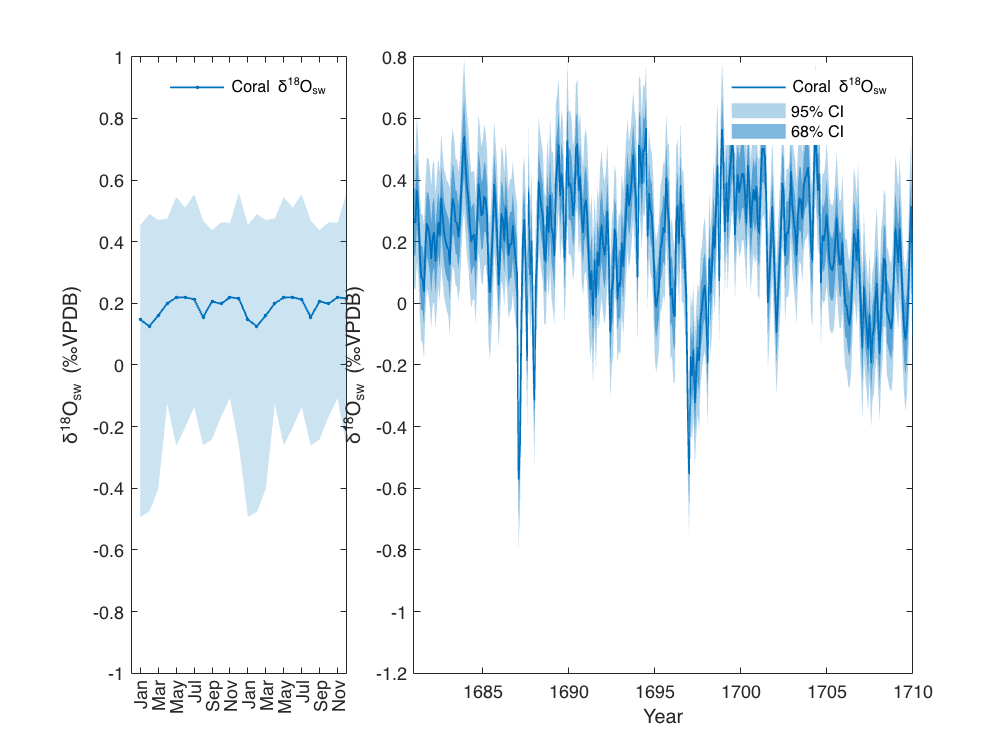

subplot(1,3,1)
hold on 
% yyaxis left
patch(seasonSSSMon,sBM_SSS,[0 0.4470 0.7410],'Edgecolor','none','Facealpha',0.2)
plot(SeasonSSS.Mon,SeasonSSS.BM,'color',[0 0.4470 0.7410],'LineWidth',1,'Marker','.','linestyle','-');
set(gca,'ylim',[-1 1])
legend('','Coral \delta^{18}O_{sw}');
xticks(1:2:24)
xticklabels({'Jan','Mar','May','Jul','Sep','Nov','Jan','Mar','May','Jul','Sep','Nov'})
ylabel('\delta^{18}O_{sw} (‰VPDB)')
box on
set(legend,'box','off')

subplot(1,3,[2,3])
hold on
plot(MC.Date,d18Osw_centred,'color',[0 0.4470 0.7410],'linestyle','-','linewidth',1)
patch(errordate,errd18Osw_MC95,[0 0.4470 0.7410],'Edgecolor','none','Facealpha',0.3)
patch(errordate,errd18Osw_MC68,[0 0.4470 0.7410],'Edgecolor','none','Facealpha',0.5)
ylabel('\delta^{18}O_{sw} (‰VPDB)')
set(gca,'xlim',[1681 1710])
box on 
lg =legend('Coral \delta^{18}O_{sw}','95% CI','68% CI','location','northeast');
set(lg,'box','off')
set(gca,'ylim',[-1.2 0.8])
xlabel('Year')
ylabel('\delta^{18}O_{sw} (‰VPDB)')

SSS = readtable('SSS.xlsx','Sheet','SSS');

Time = SSS.Date;
SODA = SSS.SODA;
EN4 = SSS.EN4;
EN4_err = SSS.EN4Error;
ARGO = SSS.ARGO;
OISSS = SSS.OISSS;
OISSS_err = SSS.OISSSerror;
IAP = SSS.IAP;

erroroisssdate = vertcat(Time(1502:1627),flipud(Time(1502:1627)));
erroren4sssdate = vertcat(Time(162:1517),flipud(Time(162:1517)));
EN4_err2 = vertcat(EN4(162:1517) + EN4_err(162:1517),flipud(EN4(162:1517) - EN4_err(162:1517)));
OISSS_err2 = vertcat(OISSS(1502:1627) + OISSS_err(1502:1627),flipud(OISSS(1502:1627) - OISSS_err(1502:1627)));

Seasons= readtable("Seasonality.xlsx",'Sheet','SSSpost2005');
Seasonality = Seasons(:,[2,5,8,11,14]);
seasonerror = Seasons(:,[1,3,4,6,7,9,10,12,13,15,16]);
sEN4 = vertcat(seasonerror.EN4l,flipud(seasonerror.EN4u));
sSODA = vertcat(seasonerror.SODAl,flipud(seasonerror.SODAu));
sIAP = vertcat(seasonerror.IAPl,flipud(seasonerror.IAPu));
sOISSS = vertcat(seasonerror.OISSSl,flipud(seasonerror.OISSSu));
sARGO= vertcat(seasonerror.ARGOl,flipud(seasonerror.ARGOu));
seasonMon = vertcat(seasonerror.Mon,flipud(seasonerror.Mon));

# figure5.6c

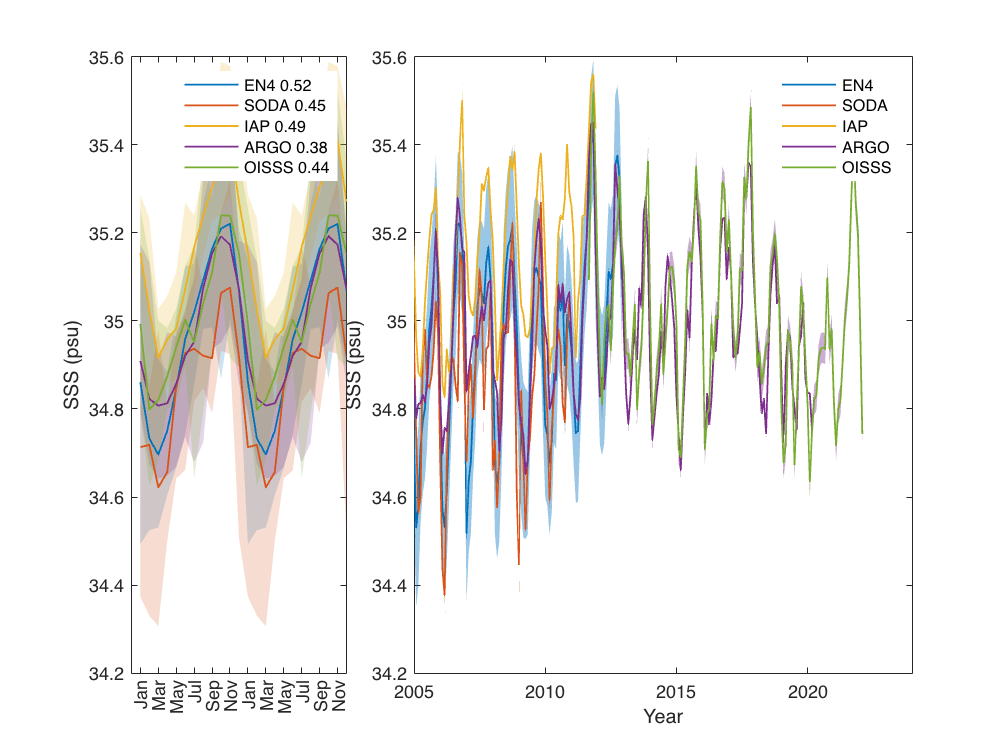

close
clf
subplot(1,3,[2 3])
hold on 
patch(erroren4sssdate,EN4_err2,[0 0.4470 0.7410],'Edgecolor','none','Facealpha',0.4)
patch(erroroisssdate,OISSS_err2,[0.4940 0.1840 0.5560],'Edgecolor','none','Facealpha',0.4)
plot(Time(162:1517),EN4(162:1517),'LineWidth',1)
plot(Time,SODA,'LineWidth',1)
plot(Time,IAP,'LineWidth',1)
plot(Time,ARGO,'LineWidth',1)
plot(Time,OISSS,'LineWidth',1)
set(gca,'xlim',[2005 2024])
ylabel('SSS (psu)')
xlabel('Year')

box on 
lg = legend('','','EN4','SODA','IAP','ARGO','OISSS');
set(lg,'box','off')
subplot(1,3,1)

hold on

patch(seasonMon,sEN4,[0, 0.4470, 0.7410],'Edgecolor','none','Facealpha',0.2)
patch(seasonMon,sSODA,[0.8500, 0.3250, 0.0980],'Edgecolor','none','Facealpha',0.2)
patch(seasonMon,sIAP,[0.9290, 0.6940, 0.1250],'Edgecolor','none','Facealpha',0.2)
patch(seasonMon,sARGO,[0.4940, 0.1840, 0.5560],'Edgecolor','none','Facealpha',0.2)
patch(seasonMon,sOISSS,[0.4660 0.6740 0.1880],'Edgecolor','none','Facealpha',0.2)
h=plot(Seasonality.Variables,'LineWidth',1);
ylabel('SSS (psu)')
legend('','','','','','EN4 0.52','SODA 0.45','IAP 0.49','ARGO 0.38','OISSS 0.44');
xticks(1:2:24)
xticklabels({'Jan','Mar','May','Jul','Sep','Nov','Jan','Mar','May','Jul','Sep','Nov'})
box on
set(legend,'box','off')

Season_a= readtable("Seasonality.xlsx",'Sheet','C5a');

SeasonSSS= readtable("Seasonality.xlsx",'Sheet','SSS_61_90');
sBM_SSS = vertcat(SeasonSSS.BMl,flipud(SeasonSSS.BMu));
sPrep = vertcat(Season_a.Prepl,flipud(Season_a.Prepu));
sCurrent = vertcat(Season_a.SODAcurrentl,flipud(Season_a.SODAcurrentu));


# Figure 5.14

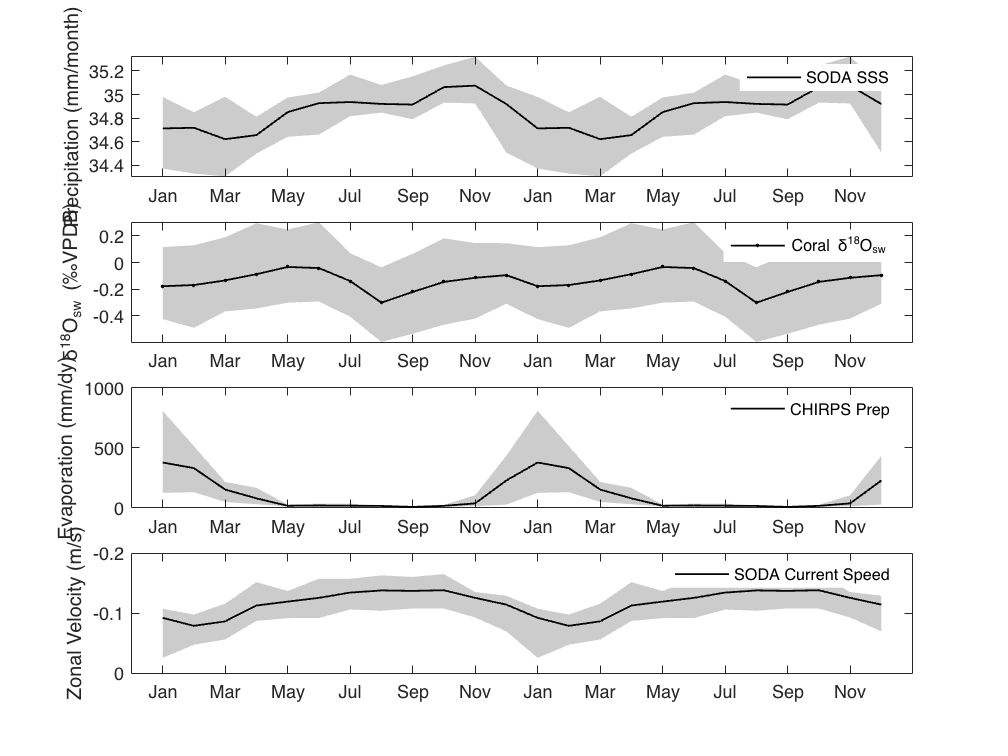

data = 82×3 table
     Yr      d18O      Sr_Ca 
    ____    _______    ______

    1913    -4.2944    8.8686
    1914    -4.4739    8.8352
    1915    -4.4225    8.8793
    1916    -4.4869    8.8486
    1917    -4.3858    8.9127
    1918    -4.3956    8.8783
    1919    -4.4125    8.8649
    1920    -4.2722     8.864
    1921    -4.3414     8.875
    1922    -4.3964    8.8671
    1923    -4.2161    8.8737
    1924    -4.3739    8.8498
    1925    -4.1972    8.8504
    1926    -4.3589    8.8062
    1927    -4.4861    8.8435
    1928      -4.49    8.8545


A =     0.0916
    0.0326
   -0.0752
   -0.0287
   -0.1587
   -0.0444
   -0.0130
    0.1305
    0.0216
   -0.0051


close
clf('reset')

subplot(4,1,1)
hold on
patch(seasonMon,sSODA,[0 0 0],'Edgecolor','none','Facealpha',0.2)
plot(Seasonality.SODA,'k-','LineWidth',1)
ylabel('Precipitation (mm/month)')
legend('','SODA SSS');
xticks(1:2:24)
xticklabels({'Jan','Mar','May','Jul','Sep','Nov','Jan','Mar','May','Jul','Sep','Nov'})
box on
set(legend,'box','off')

subplot(4,1,2)
hold on
patch(seasonSSSMon,sBM_SSS,[0 0 0],'Edgecolor','none','Facealpha',0.2)
plot(SeasonSSS.Mon,SeasonSSS.BM,'color',[0 0 0],'LineWidth',1,'Marker','.','linestyle','-');
legend('','Coral \delta^{18}O_{sw}');
xticks(1:2:24)
xticklabels({'Jan','Mar','May','Jul','Sep','Nov','Jan','Mar','May','Jul','Sep','Nov'})
ylabel('\delta^{18}O_{sw} (‰VPDB)')
box on
set(legend,'box','off')


subplot(4,1,3)
hold on
patch(seasonMon,sPrep,[0 0 0],'Edgecolor','none','Facealpha',0.2)
plot(Season_a.Mon,Season_a.Prep,'k-','LineWidth',1)
ylabel('Evaporation (mm/dy)')
legend('','CHIRPS Prep');
xticks(1:2:24)
xticklabels({'Jan','Mar','May','Jul','Sep','Nov','Jan','Mar','May','Jul','Sep','Nov'})
box on
set(legend,'box','off')

subplot(4,1,4)
hold on
patch(seasonMon,sCurrent,[0 0 0],'Edgecolor','none','Facealpha',0.2)
plot(Season_a.Mon,Season_a.SODAcurrent,'k-','LineWidth',1)
set(gca,'Ydir','reverse')
ylabel('Zonal Velocity (m/s)')
legend('','SODA Current Speed');
xticks(1:2:24)
xticklabels({'Jan','Mar','May','Jul','Sep','Nov','Jan','Mar','May','Jul','Sep','Nov'})
box on
set(legend,'box','off')

TSSSC = readtable("SSS.xlsx",'Sheet','SSS 5m');

TSSSC.Mon = categorical(TSSSC.Mon);
TSSSC.d18Osw = TSSSC.d18Osw - mean(TSSSC.d18Osw(n:end));
TSSSC.d18OswError = (d18Osw_centred_u - d18Osw_centred_l)/2;
TSSSC.SODA=TSSSC.SODA - mean(TSSSC.SODA(n:end));
%TSSSC.uwind = wind.ICOADSuflx48_100;
TSSSC.uwind = wind2.ustress;
TSSSC.vwind = wind2.vstress;
% TSSSC.vwind = wind.ICOADSvflx48_100;
TSSSC.rain = rainfall.Prcp;

gap = (10:12:4030)';
yr = (1672:2006)';
Ad18OswC = zeros(size(yr,1),1);
for i=1:size(yr,1);
    t=TSSSC.d18Osw(gap(i):(gap(i+1)-1));
    Ad18OswC(i) = mean(t,'omitnan');
i=i+1;
end

Ad18OswC_Err95 = zeros(size(yr,1),1);
for i=1:size(yr,1);
    t=TSSSC.d18OswError(gap(i):(gap(i+1)-1));
    Ad18OswC_Err95(i) = rms(t,'omitnan');
i=i+1;
end


ASODAC = zeros(size(yr,1),1);
for i=1:size(yr,1);
    t=TSSSC.SODA(gap(i):(gap(i+1)-1));
    ASODAC(i) = mean(t,'omitnan');
i=i+1;
end

Auwind = zeros(size(yr,1),1);
for i=1:size(yr,1);
    t=TSSSC.uwind(gap(i):(gap(i+1)-1));
    if sum(~isnan(t))>6
       Auwind(i) = mean(t,'omitnan');
    else
       Auwind(i) = mean(t);
    end
    i=i+1;
end

Avwind = zeros(size(yr,1),1);
for i=1:size(yr,1);
    t=TSSSC.vwind(gap(i):(gap(i+1)-1));
    if sum(~isnan(t))>6
       Avwind(i) = mean(t,'omitnan');
    else
       Avwind(i) = mean(t);
    end
    i=i+1;
end

Arain = zeros(size(yr,1),1);
for i=1:size(yr,1);
    t=rainfall.Prcp(gap(i):(gap(i+1)-1));
    if sum(~isnan(t))>6
       Arain(i) = mean(t,'omitnan');
    else
       Arain(i) = mean(t);
    end
    i=i+1;
end

APEt = zeros(size(yr,1),1);
for i=1:size(yr,1);
    t=PE.Tropical(gap(i):(gap(i+1)-1));
    APEt(i) = mean(t,'omitnan');
i=i+1;
end

APEst = zeros(size(yr,1),1);
for i=1:size(yr,1);
    t=PE.Stropical(gap(i):(gap(i+1)-1));
    APEst(i) = mean(t,'omitnan');
i=i+1;
end


Twet = vertcat(TSSSC((TSSSC.Mon=='11'),:),TSSSC((TSSSC.Mon=='12'),:),TSSSC((TSSSC.Mon=='1'),:),TSSSC((TSSSC.Mon=='2'),:),TSSSC((TSSSC.Mon=='3'),:),TSSSC((TSSSC.Mon=='4'),:));
Twet = sortrows(Twet,2);
yr_w = (1672:2007)';

wet = table2array(Twet(:,2:5));
gap = (1:6:2017)';

wetmean = zeros(336,size(wet,2));
for i=1:336;
    t=wet(gap(i):(gap(i+1)-1),:);
    wetmean(i,:) = mean(t,1);
i=i+1;
end
wetmean(:,1)=yr_w;
wetmean=array2table(wetmean,'VariableNames',{'Yr','d18Osw','d18Oswerr','SODA'});

wetd18OswC_Err95 = zeros(size(yr_w,1),1);
for i=1:size(yr_w,1);
    t=Twet.d18OswError(gap(i):(gap(i+1)-1));
    wetd18OswC_Err95(i) = rms(t,'omitnan');
i=i+1;
end

wetmean.d18Oswerr = wetd18OswC_Err95;
wetmean.d18Osw(45) = nan;
wetmean.d18Osw(60:62) = nan;
[wetmean.d18Osw,~] = fillmissing(wetmean.d18Osw,"linear","SamplePoints",wetmean.Yr); %fill gap 

wetuwnd = zeros(336,1);
for i=1:336;
    t=Twet.uwind(gap(i):(gap(i+1)-1));
    if sum(~isnan(t))>0
       wetuwnd(i) = mean(t,'omitnan');
    else
       wetuwnd(i) = mean(t);
    end
i=i+1;
end


wetvwnd = zeros(336,1);
for i=1:336;
    t=Twet.vwind(gap(i):(gap(i+1)-1));
    if sum(~isnan(t))>0
       wetvwnd(i) = mean(t,'omitnan');
    else
       wetvwnd(i) = mean(t);
    end
i=i+1;
end

wetrain = zeros(336,1);
for i=1:336;
    t=Twet.rain(gap(i):(gap(i+1)-1));
    if sum(~isnan(t))>2
       wetrain(i) = mean(t,'omitnan');
    else
       wetrain(i) = mean(t);
    end
i=i+1;
end


Tdry = vertcat(TSSSC((TSSSC.Mon=='5'),:),TSSSC((TSSSC.Mon=='6'),:),TSSSC((TSSSC.Mon=='7'),:),TSSSC((TSSSC.Mon=='8'),:),TSSSC((TSSSC.Mon=='9'),:),TSSSC((TSSSC.Mon=='10'),:));
Tdry = sortrows(Tdry,2);
Tdry = Tdry(4:2013,:);
yr_d = (1672:2006)';

dry = table2array(Tdry(:,2:5));
gap = (1:6:2011)';
drymean = zeros(335,size(dry,2));
for i=1:335;
    t=dry(gap(i):(gap(i+1)-1),:);
    drymean(i,:) = mean(t,1);
i=i+1;
end
drymean(:,1)=yr_d;
drymean=array2table(drymean,'VariableNames',{'Yr','d18Osw','d18Oswerr','SODA'});

dryd18OswC_Err95 = zeros(size(yr_d,1),1);
for i=1:size(yr_d,1);
    t=Tdry.d18OswError(gap(i):(gap(i+1)-1));
    dryd18OswC_Err95(i) = rms(t,'omitnan');
i=i+1;
end

drymean.d18Oswerr = dryd18OswC_Err95;
drymean.d18Osw(45) = nan;
drymean.d18Osw(60:62) = nan;
[drymean.d18Osw,~] = fillmissing(drymean.d18Osw,"linear","SamplePoints",drymean.Yr); %fill gap 

dryuwnd = zeros(335,1);
for i=1:335;
    t=Tdry.uwind(gap(i):(gap(i+1)-1));
    if sum(~isnan(t))>2
       dryuwnd(i) = mean(t,'omitnan');
    else
       dryuwnd(i) = mean(t);
    end
i=i+1;
end


dryvwnd = zeros(335,1);
for i=1:335;
    t=Tdry.vwind(gap(i):(gap(i+1)-1));
    if sum(~isnan(t))>0
       dryvwnd(i) = mean(t,'omitnan');
    else
       dryvwnd(i) = mean(t);
    end
i=i+1;
end


dryrain = zeros(335,1);
for i=1:335;
    t=Tdry.rain(gap(i):(gap(i+1)-1));
    if sum(~isnan(t))>2
       dryrain(i) = mean(t,'omitnan');
    else
       dryrain(i) = mean(t);
    end
i=i+1;
end

% k=1;
% [m1,n1]=butter(5,(1/10)/(0.5*k),'low');
% Ad18OswC_10 = movmean(detrend(wetmean.d18Osw(269:end)),10);
% ASODA_10 = movmean(detrend(wetmean.SODA(269:end)),10);
% [r p] = corr(Ad18OswC_10,ASODA_10)

r = 0.7366

p = 8.0864e-13

% n =length(ASODA_10);
% r1 = autocorr(ASODA_10,1);
% r1= r1(2);
% r2=autocorr(Ad18OswC_10,1);
% r2 = r2(2);
% nadj = n.*(1-r1.*r2)./(1+r1.*r2)

nadj = 4.7595

% t_stat = r * sqrt((nadj - 2) / (1 - r^2));
% p_adj = 2 * (1 - tcdf(abs(t_stat), nadj - 2))

p_adj = 0.1761

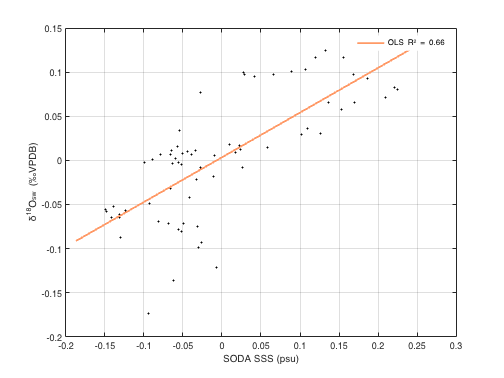

% 
% k2 = find(yr == 1940);
% tic
% tol = 1e-8;    % Tolerance
% X = ASODA_10;
% Y = Ad18OswC_10;
% 
% %% 3. Simple Linear Regression
% % Performs simple linear regression (SLR) for comparison.
% 
% R = corrcoef(X,Y);
% n = length(X);
% 
% ri = 0;
% X1 = [n,sum(X);sum(X),sum(X.*X)];               % LSE Value of 'b'
% Y1 = [sum(Y);sum(X.*Y)];                        % Polyfit can also be used
% Z1 = X1\Y1;                                     % Matrix division
% a1 = Z1(1);
% b1 = Z1(2);
% 
% sigres = sum((Y - a1 - b1.*X).^2)/(n-2);        % Sigma Residual  s^2
% delta = det(X1);  % Determinant              = n*(n-1)*varx 
% varx = var(X);
% sigb1sq = (n^2)*(n-1)*varx*sigres/(delta^2);    % Sigma(b) without weights
% sigb1 = sqrt(sigb1sq); % standard error of slope 
% Xbar = mean(X);
% 
% %siga1sq = (sigres/(varx*n))*(varx + Xbar^2) 
% siga1sq = sigres*(1/n + Xbar^2/varx/(n-1)); 
% siga1 = sqrt(siga1sq); % standard error of intercept
% A_SLR = [a1 siga1];                             % SLR Intercept
% B_SLR = [b1 sigb1];                            % SLR Slope
% 
% %---- SLR p-value ----
% 
% B1 = 0;
% t1=(b1-B1)/sigb1;    % t = (m - m0)/SE
% Pval1=2*(1-tcdf(abs(t1),n-2)); %?
% 
% %% 5. Plot
% clf
% hold on;
% grid on;   
% plot(X,Y,'.k',MarkerSize=7)
% p = min(X)-(max(X)-min(X))/10:(max(X)-min(X))/10:max(X)+(max(X)-min(X))/10;
% q3 = a1 + (b1.*p);
% h4 = plot(p,q3,'-','LineWidth',2,'Color',[1 0.6 0.4]);
% pl = legend(h4,'OLS R^{2} = 0.66');
% htext=findobj(get(pl,'children'),'type','text');
% set(pl,'Box','off')
% xlabel('SODA SSS (psu)');
% ylabel('\delta^{18}O_{sw} (‰VPDB)');
% box on

% 
% 
% disp('--------------------------------------');

--------------------------------------


% display('Simple Linear Regression:');disp(' ');

Simple Linear Regression:
 


% display('Y = a + bX');display(' ');

Y = a + bX
 


% disp('       a      siga');disp(A_SLR);

       a      siga
    0.0035    0.0057



% disp('       b      sigb');disp(B_SLR);

       b      sigb
    0.5083    0.0574



% disp(['r: ',num2str(R(1,2))]);

r: 0.73662


% disp(['r^2: ',num2str(R(1,2)^2)]);

r^2: 0.5426


% disp(['p-value: ',num2str(Pval1)]);

p-value: 8.0869e-13


% disp('--------------------------------------');

--------------------------------------


% disp(['Total no. of iterations: ',num2str(i)]);

Total no. of iterations: 336


% toc

Elapsed time is 0.948850 seconds.


%d18Osw-SSS reconstruction 
B_SLR(1) = 0.42;
B_SLR(2) = 0.03;
SSS = (Ad18OswC)./B_SLR(1);
%error propogation 
SD1 = (1/B_SLR(1)).*Ad18OswC_Err95;
SD2 = -(Ad18OswC./(B_SLR(1)^2)*B_SLR(2));
SSS_err = sqrt (SD1.^2+SD2.^2);

SSS_wet = (wetmean.d18Osw)./B_SLR(1);
SD1 = (1/B_SLR(1)).*(wetmean.d18Oswerr);
SD2 = -((wetmean.d18Osw)./(B_SLR(1)^2)*B_SLR(2));
SSS_err_wet = sqrt (SD1.^2+SD2.^2);

SSS_dry = (drymean.d18Osw)./B_SLR(1);
SD1 = (1/B_SLR(1)).*(drymean.d18Oswerr);
SD2 = -((drymean.d18Osw)./(B_SLR(1)^2)*B_SLR(2));
SSS_err_dry = sqrt (SD1.^2+SD2.^2);


# Figure 5.7

close
clf('reset')

subplot(3,3,1)
title('Annual Mean')
hold on
patchdate = vertcat(yr(1:64),flipud(yr(1:64)));
SSSerr = vertcat(SSS(1:64)+SSS_err(1:64),flipud(SSS(1:64)-SSS_err(1:64)));
patch(patchdate,SSSerr,[0 0.4470 0.7410],'edgecolor','none','facealpha',0.4)
plot(yr,SSS,'color',[0 0.4470 0.7410],'linestyle','-','LineWidth',1)
set (gca, 'XLim',[1671.583 1735])
set (gca, 'YLim',[-2 3])
ylabel('SSS (psu)')
box on 
lg =legend('','Coral \delta^{18}O_{sw}-SSS','location','northeast');

set(lg,'box','off')
xlabel('Year')

subplot(3,3,[2 3])
title('Annual Mean')
hold on
patchdate = vertcat(yr(m:end),flipud(yr(m:end)));
SSSerr = vertcat(SSS(m:end)+SSS_err(m:end),flipud(SSS(m:end)-SSS_err(m:end)));
patch(patchdate,SSSerr,[0 0.4470 0.7410],'edgecolor','none','facealpha',0.4)
plot(yr,SSS,'color',[0 0.4470 0.7410],'linestyle','-','LineWidth',1)

plot(yr,ASODAC,'linestyle','--','LineWidth',1,'color',[0.59 0.29 0.26])
plot(yr(m+54:end),ASODAC(m+54:end),'linestyle','-','LineWidth',1,'color',[0.59 0.29 0.26])

set (gca, 'XLim',[1886.583 2008])
set (gca, 'YLim',[-2 3])
ylabel('SSS (psu)')
box on 
lg =legend('','Coral \delta^{18}O_{sw}-SSS','','SODA','','','SODA SSS','','IAP SSS','location','northeast');


set(lg,'box','off')
xlabel('Year')


subplot(3,3,4)
title('Dry Season')
hold on
patchdate = vertcat(yr(1:64),flipud(yr(1:64)));
SSSerr_dry = vertcat(SSS_dry(1:64)+SSS_err_dry(1:64),flipud(SSS_dry(1:64)-SSS_err_dry(1:64)));
patch(patchdate,SSSerr_dry,[0 0.4470 0.7410],'edgecolor','none','facealpha',0.4)
plot(yr_d,SSS_dry,'color',[0 0.4470 0.7410],'linestyle','-','LineWidth',1)
set (gca, 'XLim',[1671.583 1735])
set (gca, 'YLim',[-2 3])
ylabel('SSS (psu)')
box on 
lg =legend('','Coral \delta^{18}O_{sw}-SSS','location','northeast');

set(lg,'box','off')
xlabel('Year')

subplot(3,3,[5 6])
title('Dry Season')
hold on
patchdate = vertcat(yr(m:end),flipud(yr(m:end)));
SSSerr_dry = vertcat(SSS_dry(m:end)+SSS_err_dry(m:end),flipud(SSS_dry(m:end)-SSS_err_dry(m:end)));
patch(patchdate,SSSerr_dry,[0 0.4470 0.7410],'edgecolor','none','facealpha',0.4)
plot(yr_d,SSS_dry,'color',[0 0.4470 0.7410],'linestyle','-','LineWidth',1)

plot(yr_d,drymean.SODA,'linestyle','--','LineWidth',1,'color',[0.59 0.29 0.26])
plot(yr_d(m+54:end),drymean.SODA(m+54:end),'linestyle','-','LineWidth',1,'color',[0.59 0.29 0.26])

set (gca, 'XLim',[1886.583 2008])
set (gca, 'YLim',[-2 3])
ylabel('SSS (psu)')
box on 
lg =legend('','Coral \delta^{18}O_{sw}-SSS','','SODA','','','','','','location','northeast');


set(lg,'box','off')
xlabel('Year')


subplot(3,3,7)

title('Wet Season')

hold on
patchdate = vertcat(yr_w(1:64),flipud(yr_w(1:64)));
SSSerr_wet = vertcat(SSS_wet(1:64)+SSS_err_wet(1:64),flipud(SSS_wet(1:64)-SSS_err_wet(1:64)));
patch(patchdate,SSSerr_wet,[0 0.4470 0.7410],'edgecolor','none','facealpha',0.4)
plot(yr_w,SSS_wet,'color',[0 0.4470 0.7410],'linestyle','-','LineWidth',1)
set (gca, 'XLim',[1671.583 1735])
set (gca, 'YLim',[-2 3])
ylabel('SSS (psu)')
box on 
lg =legend('','Coral \delta^{18}O_{sw}-SSS','location','northeast');

set(lg,'box','off')
xlabel('Year')

subplot(3,3,[8 9])
title('Wet Season')
hold on
patchdate = vertcat(yr_w(m:end),flipud(yr_w(m:end)));
SSSerr_wet = vertcat(SSS_wet(m:end)+SSS_err_wet(m:end),flipud(SSS_wet(m:end)-SSS_err_wet(m:end)));
patch(patchdate,SSSerr_wet,[0 0.4470 0.7410],'edgecolor','none','facealpha',0.4)
plot(yr_w,SSS_wet,'color',[0 0.4470 0.7410],'linestyle','-','LineWidth',1)

plot(yr_w,wetmean.SODA,'linestyle','--','LineWidth',1,'color',[0.59 0.29 0.26])
plot(yr_w(m+54:end),wetmean.SODA(m+54:end),'linestyle','-','LineWidth',1,'color',[0.59 0.29 0.26])

set (gca, 'XLim',[1886.583 2008])
set (gca, 'YLim',[-2 3])
ylabel('SSS (psu)')
box on 
lg =legend('','Coral \delta^{18}O_{sw}-SSS','','SODA','','','','IAP SSS','location','northeast');

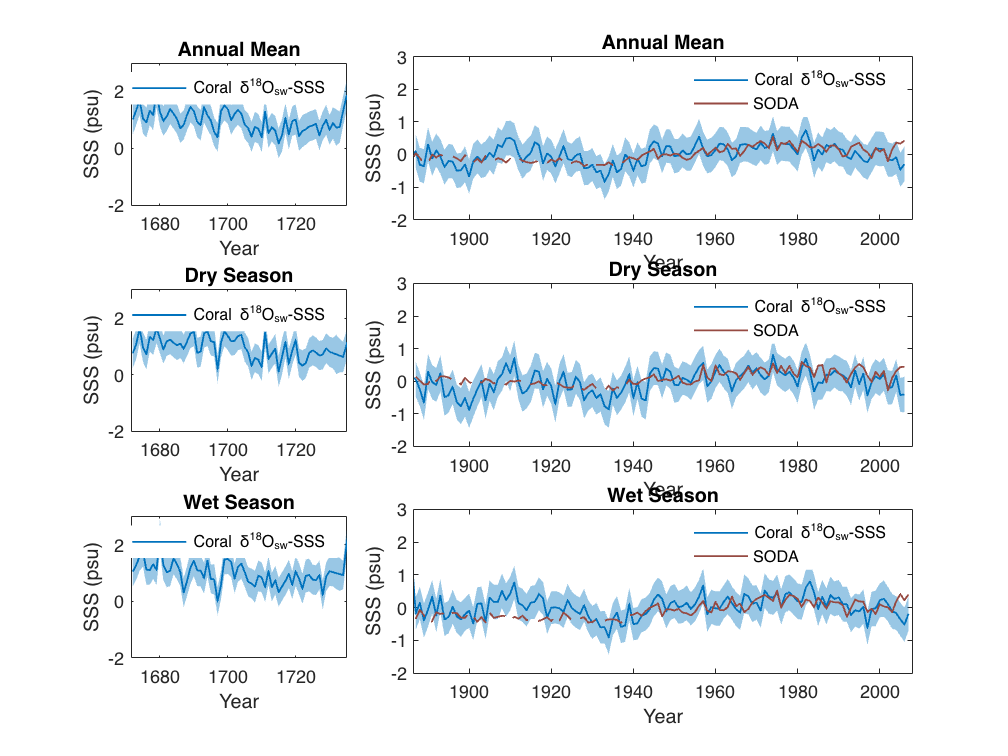


set(lg,'box','off')
xlabel('Year')

fitlm(yr(m:end),SSS_dry(m:end))

ans = Linear regression model:
    y ~ 1 + x1

Estimated Coefficients:
                   Estimate         SE         tStat       pValue  
                   _________    __________    _______    __________

    (Intercept)      -6.7934        1.7319    -3.9224    0.00014771
    x1             0.0034762    0.00088963     3.9075    0.00015601


Number of observations: 120, Error degrees of freedom: 118
Root Mean Squared Error: 0.338
R-squared: 0.115,  Adjusted R-Squared: 0.107
F-statistic vs. constant model: 15.3, p-value = 0.000156

0.0034*120 

ans = 0.4080

0.00088963*120

ans = 0.1068


fitlm(yr_w(m:end),SSS_wet(m:end))

ans = Linear regression model:
    y ~ 1 + x1

Estimated Coefficients:
                   Estimate        SE        tStat      pValue 
                   ________    __________    ______    ________

    (Intercept)     -2.8594        1.5895    -1.799    0.074559
    x1             0.001483    0.00081624    1.8169    0.071754


Number of observations: 121, Error degrees of freedom: 119
Root Mean Squared Error: 0.314
R-squared: 0.027,  Adjusted R-Squared: 0.0188
F-statistic vs. constant model: 3.3, p-value = 0.0718

0.0034*120 

ans = 0.4080

0.00088963*120

ans = 0.1068


fitlm(yr(m:end),SSS(m:end))

ans = Linear regression model:
    y ~ 1 + x1

Estimated Coefficients:
                   Estimate         SE         tStat      pValue  
                   _________    __________    _______    _________

    (Intercept)       -3.946        1.2287    -3.2115    0.0017017
    x1             0.0020278    0.00063113      3.213    0.0016937


Number of observations: 120, Error degrees of freedom: 118
Root Mean Squared Error: 0.239
R-squared: 0.0804,  Adjusted R-Squared: 0.0727
F-statistic vs. constant model: 10.3, p-value = 0.00169

0.0024539*120 

ans = 0.2945

0.00076357*120

ans = 0.0916

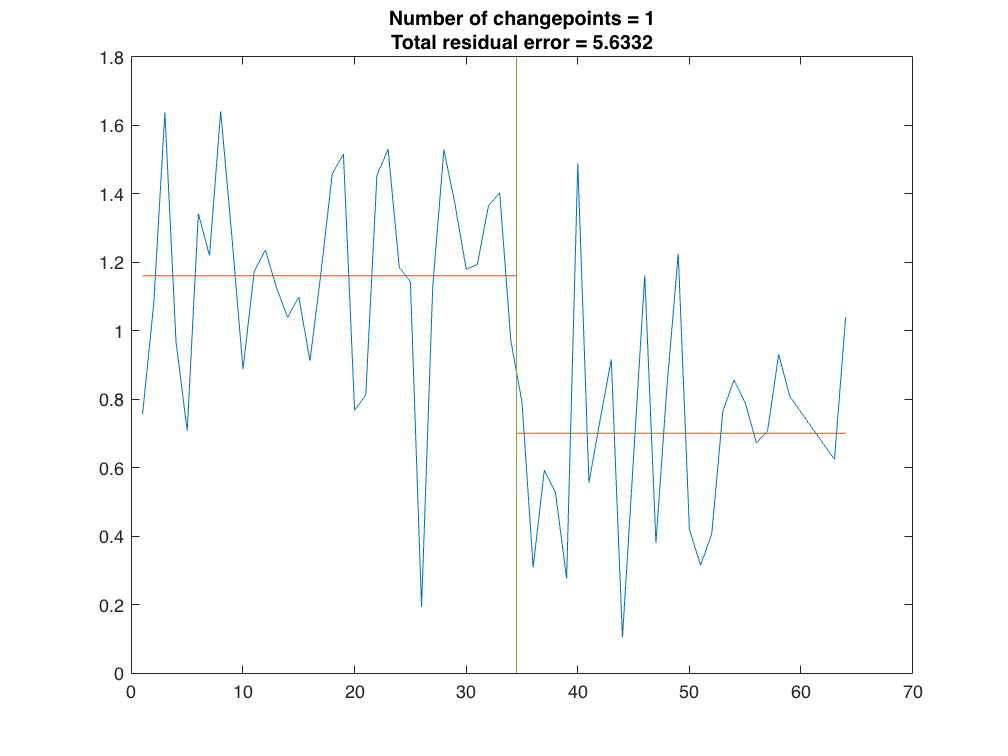

findchangepts(SSS_dry(1:64),'statistic','mean')

[h p] = ttest2(SSS_dry(1:35),SSS_dry(36:64))

h = 1

p = 1.5709e-07

mean(SSS(1:35))

ans = 1.1363

mean(SSS(36:64))

ans = 0.7627



rms(SSS_err(1:35))/sqrt(35)

ans = 0.0884

rms(SSS_err(36:64))/sqrt(28)

ans = 0.1004


[r p] = corr(detrend(Avwind(m:end),'omitnan'),detrend(SSS(m:end),'omitnan'),'rows', 'complete')

r = -0.1444

p = 0.2013

[r p] = corr(detrend(Auwind(m:end),'omitnan'),detrend(SSS(m:end),'omitnan'),'rows', 'complete')

r = 0.1556

p = 0.1682

[r p] = corr(detrend(Arain(m:end),'omitnan'),detrend(SSS(m:end),'omitnan'),'rows', 'complete')

r = -0.2562

p = 0.0410


[r p] = corr(detrend(dryvwnd(m:end),'omitnan'),detrend(drymean.d18Osw(m:end),'omitnan'),'rows', 'complete')

r = -0.1067

p = 0.3309

[r p] = corr(detrend(dryuwnd(m:end),'omitnan'),detrend(drymean.d18Osw(m:end),'omitnan'),'rows', 'complete')

r = 0.1502

p = 0.1807

[r p] = corr(detrend(dryrain(m:end),'omitnan'),detrend(drymean.d18Osw(m:end),'omitnan'),'rows', 'complete')

r = -0.1723

p = 0.1665



[r p] = corr(detrend(wetvwnd(m:end),'omitnan'),detrend(wetmean.d18Osw(m:end),'omitnan'),'rows', 'complete')

r = -0.1336

p = 0.2344

[r p] = corr(detrend(wetuwnd(m:end),'omitnan'),detrend(wetmean.d18Osw(m:end),'omitnan'),'rows', 'complete')

r = 0.1117

p = 0.3401

[r p] = corr(detrend(wetrain(m:end),'omitnan'),detrend(wetmean.d18Osw(m:end),'omitnan'),'rows', 'complete')

r = -0.2466

p = 0.0396

A = movmean(detrend(APEt(m:end),'omitnan'),5);
B = movmean(detrend(SSS(m:end),'omitnan'),5);
[r p] = corr(A,B,'rows', 'complete')
n =length(A);
r1 = autocorr(A,1);
r1= r1(2);
r2=autocorr(B,1);
r2 = r2(2);
nadj = n.*(1-r1.*r2)./(1+r1.*r2)
t_stat = r * sqrt((nadj - 2) / (1 - r^2));
p_adj = 2 * (1 - tcdf(abs(t_stat), nadj - 2))


% clf('reset')
% subplot(3,1,1)
% title('Annual Mean')
% yyaxis left
% hold on
% plot(yr,Ad18OswC,'color',[0 0.4470 0.7410],'linestyle','--','linewidth',0.5)
% plot(yr,movmean(Ad18OswC,5),'color',[0 0.3470 0.7410],'linestyle','-','linewidth',1)
% 
% ylabel('\delta^{18}O_{sw} (‰VPDB)')
% set(gca,'xlim',[1886.583 2008])
% 
% ylabel('\delta^{18}O_{sw} (‰VPDB)')
% 
% yyaxis right
% plot(yr_w,wetrain,'color',[0.8500 0.3250 0.0980],'linestyle','--','linewidth',0.5)
% plot(yr_w,movmean(wetrain,5),'color',[0.8500 0.4250 0.0980],'linestyle','-','linewidth',1)
% set(gca,'ydir','reverse')
% ylabel('Precipitation (mm/month)')
% lg =legend('','Coral \delta^{18}O_{sw}','','Precipitation','location','northeast');
% box on 
% set(lg,'box','off')
% 
% subplot(3,1,2)
% title('Wet Season')
% yyaxis left
% hold on
% plot(yr_w,wetmean.d18Osw,'color',[0 0.4470 0.7410],'linestyle','--','linewidth',0.5)
% plot(yr_w,movmean(wetmean.d18Osw,5),'color',[0 0.3470 0.7410],'linestyle','-','linewidth',1)
% 
% ylabel('\delta^{18}O_{sw} (‰VPDB)')
% set(gca,'xlim',[1886.583 2008])
% ylabel('\delta^{18}O_{sw} (‰VPDB)')
% 
% yyaxis right
% plot(yr_w,wetrain,'color',[0.8500 0.3250 0.0980],'linestyle','--','linewidth',0.5)
% plot(yr_w,movmean(wetrain,5),'color',[0.8500 0.4250 0.0980],'linestyle','-','linewidth',1)
% ylabel('Precipitation (mm/month)')
% set(gca,'ydir','reverse')
% lg =legend('','Coral \delta^{18}O_{sw}','','Precipitation','location','northeast');
% box on 
% set(lg,'box','off')
% 
% subplot(3,1,3)
% title('Dry Season')
% yyaxis left
% hold on
% plot(yr_d,drymean.d18Osw,'color',[0 0.4470 0.7410],'linestyle','--','linewidth',0.5)
% plot(yr_d,movmean(drymean.d18Osw,5),'color',[0 0.3470 0.7410],'linestyle','-','linewidth',1)
% 
% ylabel('\delta^{18}O_{sw} (‰VPDB)')
% set(gca,'xlim',[1886.583 2008])
% xlabel('Year')
% ylabel('\delta^{18}O_{sw} (‰VPDB)')
% 
% yyaxis right
% plot(yr_w,wetrain,'color',[0.8500 0.3250 0.0980],'linestyle','--','linewidth',0.5)
% plot(yr_w,movmean(wetrain,5),'color',[0.8500 0.4250 0.0980],'linestyle','-','linewidth',1)
% ylabel('Precipitation (mm/month)')
% set(gca,'ydir','reverse')
% lg =legend('','Coral \delta^{18}O_{sw}','','Precipitation','location','northeast');
% box on 
% set(lg,'box','off')


# Figure 5.11

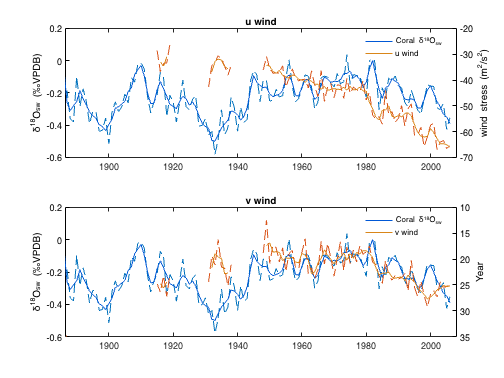

close
clf('reset')
subplot(2,1,2)
title('v wind')
yyaxis left
hold on
plot(yr,Ad18OswC,'color',[0 0.4470 0.7410],'linestyle','--','linewidth',1)
plot(yr,movmean(Ad18OswC,3),'color',[0 0.3470 0.8410],'linestyle','-','linewidth',1)

ylabel('\delta^{18}O_{sw} (‰VPDB)')
set(gca,'xlim',[1886.583 2008])

ylabel('\delta^{18}O_{sw} (‰VPDB)')

yyaxis right
plot(yr,Avwind,'color',[0.8500 0.3250 0.0980],'linestyle','--','linewidth',1)
plot(yr,movmean(Avwind,3),'color',[0.8500 0.5250 0.0980],'linestyle','-','linewidth',1)
set(gca,'ydir','reverse')
ylabel('wind stress (m^{2}/s^{2})')
lg =legend('','Coral \delta^{18}O_{sw}','','v wind','location','northeast');
box on 
set(lg,'box','off')
ylabel('Year')
ax = gca;
ax.YAxis(1).Color = 'k';
ax.YAxis(2).Color = 'k';


subplot(2,1,1)
title('u wind')
yyaxis left
hold on
plot(yr,Ad18OswC,'color',[0 0.4470 0.7410],'linestyle','--','linewidth',1)
plot(yr,movmean(Ad18OswC,3),'color',[0 0.3470 0.8410],'linestyle','-','linewidth',1)

ylabel('\delta^{18}O_{sw} (‰VPDB)')
set(gca,'xlim',[1886.583 2008])

ylabel('\delta^{18}O_{sw} (‰VPDB)')

yyaxis right
plot(yr,Auwind,'color',[0.8500 0.3250 0.0980],'linestyle','--','linewidth',1)
plot(yr,movmean(Auwind,3),'color',[0.8500 0.5250 0.0980],'linestyle','-','linewidth',1)
ylabel('wind stress (m^{2}/s^{2})')
lg =legend('','Coral \delta^{18}O_{sw}','','u wind','location','northeast');
box on 
set(lg,'box','off')

ax = gca;
ax.YAxis(1).Color = 'k';
ax.YAxis(2).Color = 'k';

# Figure 5.10

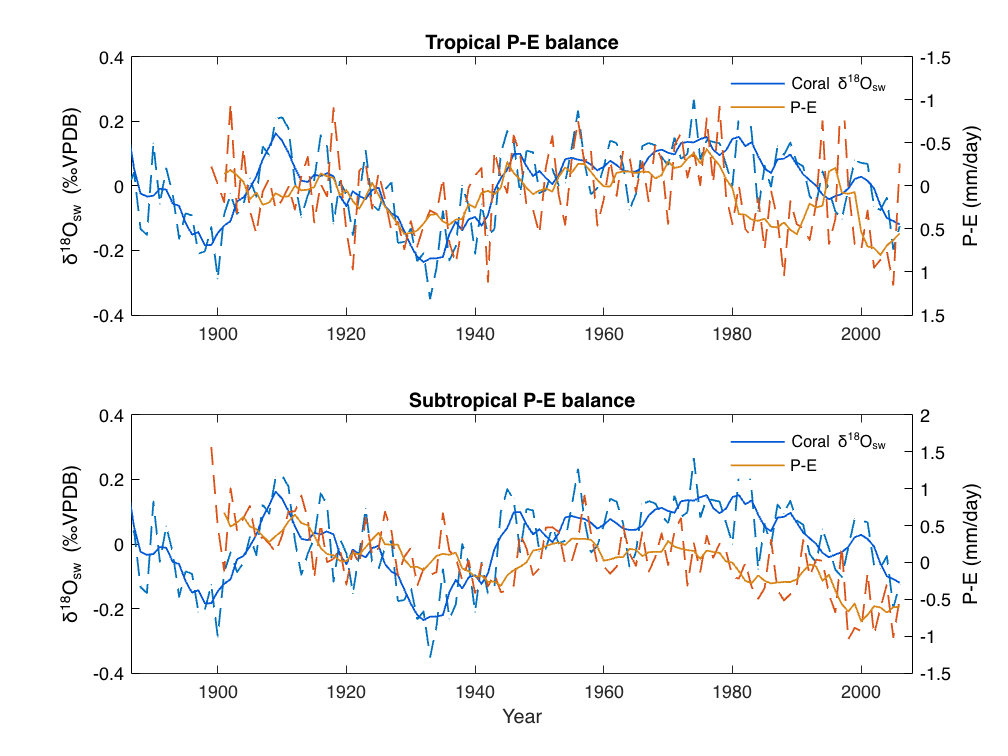

close
clf
subplot(2,1,1)
title('Tropical P-E balance')
yyaxis left
hold on
plot(yr,Ad18OswC,'color',[0 0.4470 0.7410],'linestyle','--','linewidth',1)
plot(yr,movmean(Ad18OswC,5),'color',[0 0.3470 0.8410],'linestyle','-','linewidth',1)

ylabel('\delta^{18}O_{sw} (‰VPDB)')
set(gca,'xlim',[1886.583 2008])

ylabel('\delta^{18}O_{sw} (‰VPDB)')

yyaxis right
plot(yr,APEt,'color',[0.8500 0.3250 0.0980],'linestyle','--','linewidth',1)
plot(yr,movmean(APEt,5),'color',[0.8500 0.5250 0.0980],'linestyle','-','linewidth',1)
set(gca,'ydir','reverse')
ylabel('P-E (mm/day)')
lg =legend('','Coral \delta^{18}O_{sw}','','P-E','location','northeast');
box on 
set(lg,'box','off')

ax = gca;
ax.YAxis(1).Color = 'k';
ax.YAxis(2).Color = 'k';


subplot(2,1,2)
title('Subtropical P-E balance')
yyaxis left
hold on
plot(yr,Ad18OswC,'color',[0 0.4470 0.7410],'linestyle','--','linewidth',1)
plot(yr,movmean(Ad18OswC,5),'color',[0 0.3470 0.8410],'linestyle','-','linewidth',1)

ylabel('\delta^{18}O_{sw} (‰VPDB)')
set(gca,'xlim',[1886.583 2008])

ylabel('\delta^{18}O_{sw} (‰VPDB)')

yyaxis right
plot(yr,APEst,'color',[0.8500 0.3250 0.0980],'linestyle','--','linewidth',1)
plot(yr,movmean(APEst,5),'color',[0.8500 0.5250 0.0980],'linestyle','-','linewidth',1)
ylabel('P-E (mm/day)')
xlabel('Year')
lg =legend('','Coral \delta^{18}O_{sw}','','P-E','location','northeast');
box on 
set(lg,'box','off')

ax = gca;
ax.YAxis(1).Color = 'k';
ax.YAxis(2).Color = 'k';

# Figure 5.15

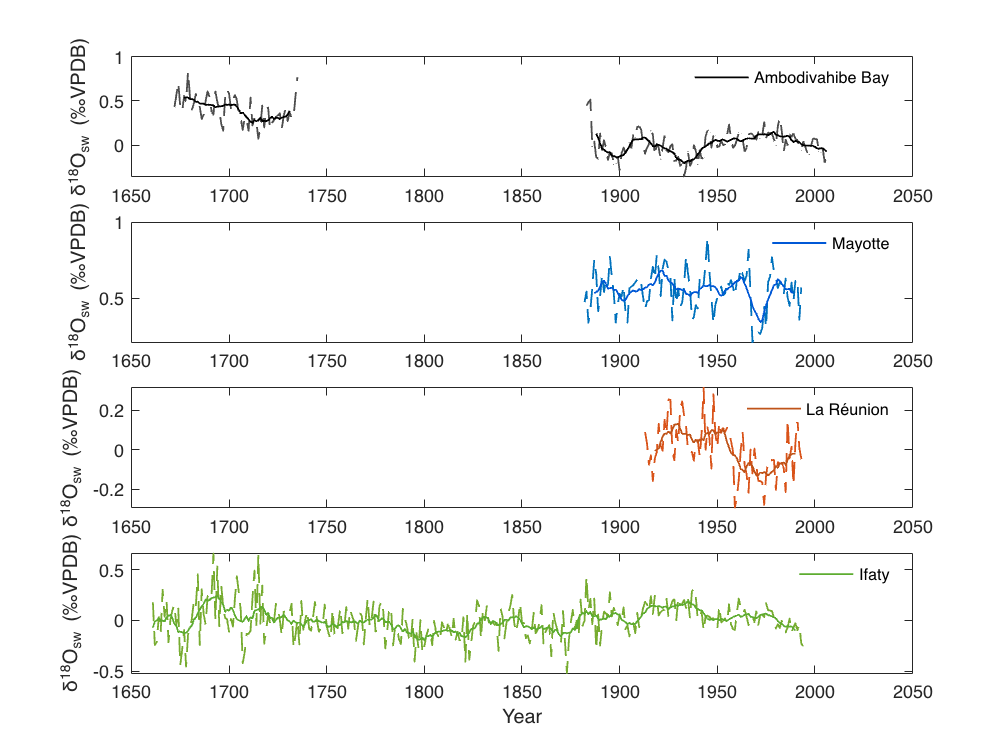

data = readtable('d18oswio.xlsx');
close 
clf
subplot(4,1,1)
hold on
plot(data.Yr,data.BM,'color',[0.3 0.3 0.3],'linestyle','--','linewidth',1)
plot(data.Yr,movmean(data.BM,10),'color',[0 0 0],'linestyle','-','linewidth',1)
ylabel('\delta^{18}O_{sw} (‰VPDB)')
lg =legend('','Ambodivahibe Bay');
box on 
set(lg,'box','off')
set(gca,'xlim',[1650 2050])

subplot(4,1,2)
hold on
plot(data.Yr,data.Mayotte,'color',[0 0.4470 0.7410],'linestyle','--','linewidth',1)
plot(data.Yr,movmean(data.Mayotte,10),'color',[0 0.3470 0.8410],'linestyle','-','linewidth',1)
ylabel('\delta^{18}O_{sw} (‰VPDB)')
lg =legend('','Mayotte');
box on 
set(lg,'box','off')
set(gca,'xlim',[1650 2050])
subplot(4,1,3)
hold on
plot(data.Yr,data.ReUnion,'color',[0.8500 0.3250 0.0980],'linestyle','--','linewidth',1)
plot(data.Yr,movmean(data.ReUnion,10),'color',[0.7500 0.3250 0.0980],'linestyle','-','linewidth',1)
ylabel('\delta^{18}O_{sw} (‰VPDB)')
lg =legend('','La Réunion');
box on 
set(lg,'box','off')
set(gca,'xlim',[1650 2050])
subplot(4,1,4)
hold on
plot(data.Yr,data.Ifaty,'color',[0.4660 0.6740 0.1880],'linestyle','--','linewidth',1)
plot(data.Yr,movmean(data.Ifaty,10),'color',[0.3660 0.6740 0.1880],'linestyle','-','linewidth',1)
ylabel('\delta^{18}O_{sw} (‰VPDB)')
lg =legend('','Ifaty');
box on 
set(lg,'box','off')
set(gca,'xlim',[1650 2050])
xlabel('Year')